# **Tutorial: Overview of how to use the MINT toolbox -  MI**

This tutorial provides an introduction on how to use the MI function from the MINT toolbox to compute Mutual Information. 

## Data simulation

This simulation models neural activity in response to two types of stimuli over multiple trials, simulating a network of 20 neurons across 60 ms and 200 trials. Each neuron has a baseline activity with noise. Neurons are categorized as responsive to stimulus 1, stimulus 2, or non-responsive. When the assigned stimulus is presented, responsive neurons show an activity spike within a random window (variable in onset and duration), while non-responsive neurons maintain baseline activity. You can change the parameters of the simulation in order to explore the influence on the results.

本教程介绍如何使用MINT工具箱中的MI函数计算互信息。

**数据模拟**

本次模拟模拟了在多种刺激类型下、跨多个试次的神经活动，模拟了一个包含20个神经元、跨时60毫秒、共200个试次的网络。每个神经元具有带噪声的基线活动。神经元被归类为对刺激1有反应、对刺激2有反应或无反应。当呈现指定的刺激时，有反应的神经元会在一个随机的时间窗口内（起始时间和持续时间可变）表现出活动尖峰，而无反应神经元则保持基线活动。您可以更改模拟参数，以探究其对结果的影响。

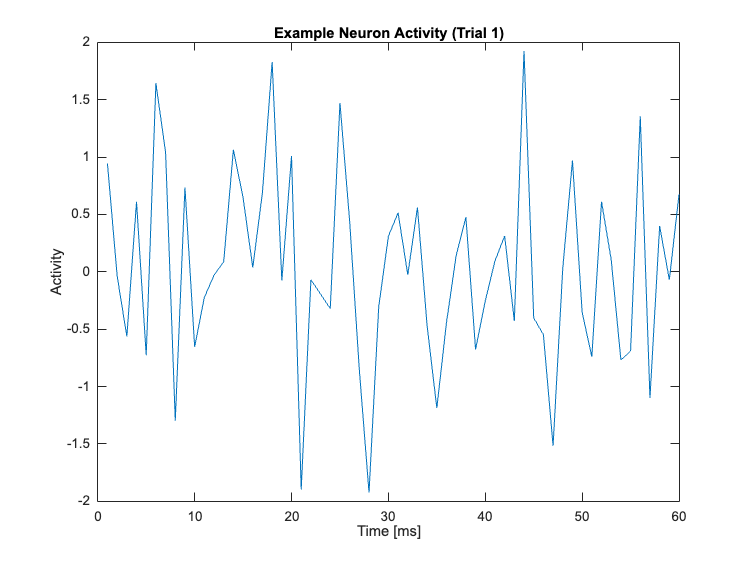

clc, clear  % 清空命令窗口和工作空间变量
rng(0)      % 设置随机数生成器种子为0，确保结果可重复
nNeurons = 20;     % 神经元数量：20个      
nTimepoints = 60;  %ms % 每个试次的时间点数：60个（以毫秒为单位）     
nTrials = 100;  % 试次数量：100次

baselineActivity = 0.2;  % Baseline activity level，基线活动水平：0.2
noiseLevel = 0.9;        % Level of random noise in baseline activity，基线活动中的随机噪声水平：0.9
stimulus_amplitude = 3;  % Increase in activity for stimulus-responsive neurons，刺激响应神经元的活动增幅：3

stimulus = randi([1, 2], 1, nTrials); % 生成每个试次的刺激类型：随机生成1或2（两种刺激类型）[1xnTrials]

% Assign neurons to respond to either stimulus 1, stimulus 2, or not respond, 将神经元分配到对刺激1有反应、对刺激2有反应或无反应的类型中
respond_to_stimulus1 = randperm(nNeurons, floor(nNeurons / 3)); % 随机选择约1/3的神经元对刺激1有反应
remaining_neurons = setdiff(1:nNeurons, respond_to_stimulus1); 
respond_to_stimulus2 = remaining_neurons(randperm(length(remaining_neurons), floor(nNeurons / 3))); % 从剩余神经元中再随机选择约总体1/3的神经元对刺激2有反应
non_responsive_neurons = setdiff(1:nNeurons, [respond_to_stimulus1, respond_to_stimulus2]); % 剩下的神经元为无反应神经元

% Create baseline neural activity (nNeurons x nTimepoints x nTrials)，创建基线神经活动数据（维度：神经元 × 时间点 × 试次）
neural_data = baselineActivity + noiseLevel * randn(nNeurons, nTimepoints, nTrials); % 初始化为基线活动值加上高斯分布噪声

% Embed stimulus-related activity for neurons responsive to stimulus 1,为对刺激1有反应的神经元嵌入与刺激相关的活动增强
for neuron = respond_to_stimulus1  % 遍历每个对刺激1有反应的神经元
    response_window_start = randi([10, 30]); % Random start of window,随机生成响应窗口的起始时间（10到30毫秒之间）
    response_window_length = randi([5, 25]); % Random length of window,随机生成响应窗口的长度（5到25毫秒之间）
    response_window_end = min(response_window_start + response_window_length, nTimepoints); % 计算响应窗口的结束时间，确保不超过总时间点数   
    % Increase activity during the response window in each trial where stimulus == 1, 在每个刺激类型为1的试次中，在响应窗口内增加神经元活动
    for trial = 1:nTrials
        if stimulus(trial) == 1 % 如果当前试次的刺激类型为1
            neural_data(neuron, response_window_start:response_window_end, trial) = ...
                neural_data(neuron, response_window_start:response_window_end, trial) + stimulus_amplitude; % 在响应窗口内增加刺激幅度值
        end
    end
end

% Embed stimulus-related activity for neurons responsive to stimulus 2
for neuron = respond_to_stimulus2
    response_window_start = randi([10, 30]); % Random start of window 
    response_window_length = randi([5, 25]); % Random length of window
    response_window_end = min(response_window_start + response_window_length, nTimepoints);    
    % Increase activity during the response window in each trial where stimulus == 2
    for trial = 1:nTrials
        if stimulus(trial) == 2
            neural_data(neuron, response_window_start:response_window_end, trial) = ...
                neural_data(neuron, response_window_start:response_window_end, trial) + stimulus_amplitude;
        end
    end
end

% Visualize example data for a single neuron across time in a single trial,可视化单个神经元在单个试次中随时间变化的示例活动数据
figure; % 创建新图形窗口
plot(squeeze(neural_data(1, :, 1))); % 绘制第一个神经元在第一个试次中所有时间点的活动数据
title('Example Neuron Activity (Trial 1)'); % 设置图形标题
xlabel('Time [ms]'); % 设置x轴标签
ylabel('Activity');  % 设置y轴标签

### Settings of MI to compute the Mutual Information

The `MI` function is designed to compute mutual information (MI) and related information-theoretic measures between two sets of input data, referred to as A and B. These inputs are provided as a cell array, where `inputs{1}` corresponds to the first dataset (A) and `inputs{2}` corresponds to the second dataset (B). If either A, B, or both inputs are time series, the output will also be returned as a time series.

You can specify which types of entropy calculations you would like to perform by passing a cell array of strings in the `req`O`utputs` parameter. To compute the Mutual Information of A and B, specify {`'I(A;B)'} `as output request.

The `MI` function provides an array of optional parameters that can be specified using a structure. These options allow for customization of the mutual information calculations according to the user's requirements. If these parameters are not provided, the function will default to predefined settings.

**计算互信息的MI函数设置**

MI函数旨在计算两组输入数据（称为A和B）之间的互信息及相关信息论度量。输入以元胞数组形式提供，其中 inputs{1} 对应第一个数据集（A），inputs{2} 对应第二个数据集（B）。如果A、B或两者均为时间序列，则输出也将以时间序列形式返回。

您可以通过在 `reqOutputs` 参数中传递一个字符串元胞数组来指定要执行的熵计算类型。要计算A和B的互信息，请指定 `{'I(A;B)'}` 作为输出请求。

MI函数提供了一系列可选参数，可通过结构体进行指定。这些选项允许根据用户需求自定义互信息计算。如果未提供这些参数，函数将使用预定义的默认设置。

The options you can define are: 

- 'bin_method'                 : specifies the method used to bin the data                                                   (default: none)                     

- 'n_bins'                         : specifies the number of bins                                                                        (default: 3)

- 'bias'                             : specifies the bias correction method                                                            (default: naive)

- ('xtrp'/'shuff')                 : further specification for the bias correction methods 'qe' and 'shuffSub'      (default: 10 xtrp/20 shuff)

- 'supressWarnings'        : option to supress warnings e.g. for missing opts fields                                (default: false)

- 'NaN_handling'             : specify how to deal with NaN values in the data                                          (default: error)

- 'computeNulldist'          : If set to true, generates a null distribution based on the specified inputs     (default: false)

可以定义的选项包括：

- `'bin_method'`            ：指定用于数据分箱的方法。                                                                          (默认：none)

- `'n_bins'`                     ：指定分箱数量。                                                                                            (默认：3)

- `'bias'`                         ：指定偏置校正方法。                                                                                     (默认：naive)

- `('xtrp'/'shuff') ` ：为偏置校正方法 'qe' 和 'shuffSub' 提供进一步说明。                                   (默认：10 xtrp/20 shuff)

- `'supressWarnings'` ：选择是否抑制警告（例如，针对缺失的opts字段）。                                   (默认：false)

- `'NaN_handling'`        ：指定如何处理数据中的NaN值。                                                                   (默认：error)

- `'computeNulldist'`  ：如果设置为true，将根据指定的输入生成一个零分布。                               (默认：false)

% To bin your data, you must specify both the binning method and the number of bins. ,要对数据进行分箱，您必须同时指定分箱方法和分箱数量。
% You can set different methods or number of bins for each input. If only one is provided, it will be applied to all inputs. ,您可以为每个输入设置不同的方法或分箱数量。如果只提供了一个设置，它将应用于所有输入。
% For more details type 'help binning' in your Command Window. 更多详细信息，请在命令窗口中输入 'help binning'。
MI_opts.bin_method = {'eqpop','none'};     % Options: % 设置分箱方法：第一个输入使用等数量分箱('eqpop')，第二个输入不分箱('none')                                     
                                            % 'eqpop' (equal population), -  等数量分箱（每个箱中数据点数量大致相等）
                                            % 'eqspace' (equal spacing), - 等间距分箱（每个箱的宽度相等）
                                            % 'userEdges', - 用户自定义箱边界
                                            % 'none' (no binning) , - 不分箱                                   
MI_opts.n_bins = {3};                       % Specify an integer for the number of bins,  - 指定分箱数量：将第一个输入分3个箱.注意：这是一个元胞数组，可以为每个输入指定不同的分箱数量
    


% To correct for sampling bias, you can specify methods for bias correction in the MINT toolbox. 为了校正采样偏置，您可以在MINT工具箱中指定偏置校正方法。
% If its not naive you will get the naive values as the second output of the functions. 如果不使用朴素估计('naive')，函数的第二个输出将是朴素估计值。
% For more details type 'help correction' in your Command Window.更多详细信息，请在命令窗口中输入 'help correction'。
MI_opts.bias = 'pt';             % Options: % 设置偏置校正方法为'pt'（Panzeri-Treves校正法）                                          
                                            % 'naive' (no bias correction)  - 无偏置校正（直接估计）                                                                       
                                            % 'qe' (Quadratic Extrapolation),  - 二次外推法
                                            % 'le' (Linear Extrapolation),  - 线性外推法
                                            % 'qe_shuffSub' (Quadratic with Shuffle Subtraction), - 带打乱减法的二次外推法
                                            % 'le_shuffSub' (Linear with Shuffle Subtraction),  - 带打乱减法的线性外推法
                                            % 'shuffSub' (Shuffle Subtraction), - 打乱减法
                                            % 'pt' (Panzeri-Treves),- Panzeri-Treves校正法 
                                            % 'bub' (BUB Correction), - BUB校正法
                                            % 'shuffCorr' (Shuffle Correction) - 打乱校正法

% If you use 'qe' you have to specify the number of extrapolations (opts.xtrp) the correction function should to. 如果使用'qe'方法，必须指定外推次数(opts.xtrp)。
% If you use 'shuffSub' you have to specify the number of shufflings (opts.shuff) the correction function should to. 如果使用'shuffSub'方法，必须指定打乱次数(opts.shuff)。
MI_opts.shuff = 2;   % 设置打乱次数为2次（适用于'shuffSub'方法）
MI_opts.xtrp = 8; % 设置外推次数为8次（适用于'qe'方法）
MI_opts.parallel = true;% 启用并行计算以加速处理（如果支持）

% Several functions give you warning, e.g. if you did not specify an opts field that is needed,多个函数会发出警告，例如如果您没有指定必需的opts字段，
% and the function is using the default it will inform you. If you don't want to get these warning you can supress them with the opts field 而函数使用默认值时，它会通知您。如果您不想收到这些警告，可以通过opts字段supressWarnings来抑制它们。
% supressWarnings (default: false).默认值为false（显示警告）。
MI_opts.supressWarnings = true; % 设置supressWarnings为true，抑制警告信息

MI_opts.NaN_handling = 'removeTrial';        % Options: 设置NaN值的处理方式为'removeTrial'                                          
                                             % 'error' (Throws an error if
                                             % NaN values are detected in any input),'error' - 在任何输入中检测到NaN值时抛出错误
                                             % 'removeTrial' (Removes trials (across all variables) that contain NaN values),% 'removeTrial' - 删除包含NaN值的试次（跨所有变量）  

### MI Outputs

The function can output three variables based on the specified settings:

- **MI_values**: This is a cell array containing the information values based on the specified reqOutputs argument. Each cell represents one requested output in the same order as specified

- **MI_naive**: This cell array contains the naive estimates. These estimates are calculated without any bias correction. It is important to note that if no bias correction is performed during the computation, the MI_values will be identical to the MI_naive values.

- **MI_nullDist**: This output contains the results of the null distribution computation, which is useful for significance testing. If the null distribution is not computed, this output will be zero.   

**MI输出**

根据指定设置，该函数可以输出三个变量：

- `MI_values`：这是一个元胞数组，包含基于 `reqOutputs` 参数指定的信息值。每个元胞代表一个请求的输出，顺序与指定顺序一致。

- `MI_naive`：此元胞数组包含未经任何偏置校正的朴素估计值。请注意，如果在计算过程中未执行偏置校正，则 `MI_values` 将与 `MI_naive` 值相同。

- `MI_nullDist`：此输出包含零分布计算的结果，这对于显著性检验非常有用。如果未计算零分布，此输出将为零。

### How to compute the Mutual Information

#### 1. Compute the Mutual Information of each Neuron across time

If you want to compute the Mutual Information for each neuron based on the above defined settings, you can call the MI function as follows: 

**如何计算互信息**

**1. 计算每个神经元随时间变化的互信息**

如果您想根据上述设置计算每个神经元的互信息，可以按如下方式调用MI函数：

MI_singleNeuron = zeros(nNeurons, nTimepoints); % 初始化一个矩阵来存储每个神经元在每个时间点的互信息值，% 维度：神经元数量 × 时间点数量
reqOutputs = {'I(A;B)'};% 指定需要计算的输出类型：互信息 I(A;B)
for neuron = 1:nNeurons % 循环遍历每个神经元，计算其互信息
    neuron_data = neural_data(neuron,:,:); % 提取当前神经元的神经活动数据 % 维度：1 × 时间点 × 试次
    inputs = {neuron_data, stimulus};  % 构建MI函数的输入：{神经活动数据, 刺激类型} 
    
    tti = squeeze(neuron_data);% 使用squeeze函数移除单维度，将数据转换为二维矩阵% 维度：时间点 × 试次
    
    % tt = MI({tti(1,:), stimulus}, reqOutputs, MI_opts); % 注释掉的备用代码行：使用另一种方式调用MI函数
    MI_singleNeuron(neuron,:) = cell2mat(MI(inputs, reqOutputs, MI_opts)); % 计算当前神经元的互信息，并将结果存储在矩阵中 % cell2mat将元胞数组转换为常规数组
end 

Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option "computeNulldist" was not specified. Using default value false.
Option

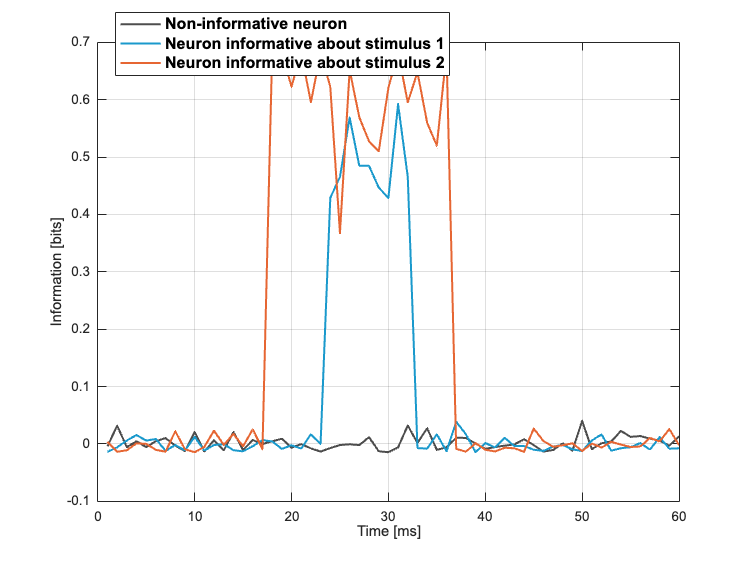


% Select example neurons for each group，选择每组中的示例神经元进行可视化
non_responsive_neuron = non_responsive_neurons(1); % 从无反应神经元组中选择第一个神经元作为示例
responsive_neuron_1 = respond_to_stimulus1(1); % 从对刺激1有反应的神经元组中选择第一个神经元作为示例    
responsive_neuron_2 = respond_to_stimulus2(1); % 从对刺激2有反应的神经元组中选择第一个神经元作为示例     

time = 1:nTimepoints;% 创建时间轴向量（1到总时间点数）
figure;% 创建新图形窗口
plot(time, MI_singleNeuron(non_responsive_neuron, :), 'Color', [0.3, 0.3, 0.3], 'LineWidth', 1.5); % 绘制无反应神经元的互信息随时间变化曲线 % 使用灰色线条，线宽1.5
hold on; % 保持图形，在同一坐标系中绘制多条曲线
plot(time, MI_singleNeuron(responsive_neuron_1, :), 'Color', [0.1, 0.6, 0.8], 'LineWidth', 1.5); % 绘制对刺激1有反应的神经元的互信息随时间变化曲线 % 使用青色线条，线宽1.5  
plot(time, MI_singleNeuron(responsive_neuron_2, :), 'Color', [0.9, 0.4, 0.2], 'LineWidth', 1.5); % 绘制对刺激2有反应的神经元的互信息随时间变化曲线 % 使用橙色线条，线宽1.5  
hold off; % 结束图形保持状态

xlabel('Time [ms]');% 设置x轴标签
ylabel('Information [bits]');% 设置y轴标签
legend(["Non-informative neuron", "Neuron informative about stimulus 1", "Neuron informative about stimulus 2"], "FontSize", 12, "FontWeight", "bold", "Position", [0.1735 0.8668 0.4071, 0.1119])% 添加图例，指定图例内容和样式% 字体大小12，粗体，图例位置坐标

grid on; % 显示网格线

#### 2. Test for significance

To test for significance, you may want to generate a null distribution.The functions in the MINT toolbox offer an option to do this through the `opts.computeNulldist` parameter. To obtain the null distribution, set this option to `true` and specify the number of samples using `opts.n_samples` (default is 100). 

You can also indicate which variables should be shuffled to create the null distribution or specify if the shuffling should be conditioned on another variable using `opts.shuffling`. If you provide multiple shuffling definitions, the function will output one null distribution for each shuffling definition specified. (default: 'A' (just the firstinput variable is going to be shuffled). 

You can also specify the dimension that should be shuffled with opts.dim_shuffle. For 'Trials' it shuffles the last dimension, for 'Objects' the first and for 'Timepoints' the second.

For more information, type `help create_nullDist` in your Command Window.

To test for example for which timepoints a neuron carries significant information about the stimulus, we can first compute the null Distribution and then test for significance 

**2. 显著性检验**

要进行显著性检验，您可能需要生成一个零分布。MINT工具箱中的函数提供了通过 `opts.computeNulldist` 参数实现此功能。要获取零分布，请将此选项设置为 `true`，并使用 `opts.n_samples` 指定抽样数量（默认值为100）。

您还可以指示应打乱哪些变量以创建零分布，或使用 `opts.shuffling` 指定打乱是否应基于另一个变量进行条件化。如果提供了多个打乱定义，函数将为每个指定的打乱定义输出一个零分布。（默认：'A'，仅打乱第一个输入变量）。

您还可以使用 `opts.dim_shuffle` 指定应打乱的维度。对于 'Trials'，打乱最后一个维度；对于 'Objects'，打乱第一个维度；对于 'Timepoints'，打乱第二个维度。

更多信息，请在命令窗口中输入 `help create_nullDist`。

例如，为了检验神经元在哪些时间点携带关于刺激的显著信息，我们可以首先计算零分布，然后进行显著性检验：

MI_opts.computeNulldist = true;  
MI_opts.parallel_sampling = true;   
MI_opts.n_samples = 100;
MI_opts.shuffling = {'A'};
MI_opts.dim_shuffle = {'Trials'};

timePointInfo = find(MI_singleNeuron(respond_to_stimulus1(1),:) > 0.4);
neuron_data = neural_data(respond_to_stimulus1(1),:,:);
inputs = {neuron_data, stimulus};   
[~, ~, MI_nullDist] = MI(inputs, reqOutputs, MI_opts);   % this can take a while, to speed up the computation you can reduce the number of samples in n_samples

MI_nullDist = cell2mat(MI_nullDist);
MI_info = MI_singleNeuron(respond_to_stimulus1(1),:);

p_values = zeros(1, nTimepoints);
for t = 1:nTimepoints
    [~, p_values(t)] = ttest(MI_nullDist(:, t), MI_info(t));         
end

#### 3. Compute the Population Information  

When analysing high-dimensional neuronal responses (such as the activity of populations of many neurons), the data space grows exponentially, making it inefficient to directly sample the joint response probabilities from the data. Therefore the MINT toolbox provides dimensionality reduction methods for the population activity. You can find the dimensionality reduction methods in the folder 'function_wrapper', including:

- glm_wrapper

- svm_wrapper

- pca_wrapepr

- nmf_wrapper

SVM_wrapper

Here you will find an example how to use the svm_wrapper. Similar to the main functions, the dimensionality reduction wrapper has three inputs. The first one is the data and for the other two, which are optional, the user can specify the requested outputs and a structure with customized options.

For the svm_wrapper these options include:

- 'svm_family'                 : Type of SVM to use, options include 'linear' and 'RBF'                                                    (default: linear)

- 'cv'                                : specifies the crossvalidation method to fit the model                                                      (default: Resubstitution (train and fit on all trials))                     

- 'libsvm'                         : specifies if the function uses libsvm or matlab functions                                                 (default: false)

- 'Standardize'                :  Boolean indicating whether to standardize features                                                       (default: true)

- 'optim_opts'                  : structure specifing options for hyperparameter optimization crossvalidation                  (default: empty struct)

- 'hp_C'                           : if no hyperparameter is specified, this parameter can define C                                       (default: 1)

- 'hp_gamma'                  : if no hyperparameter is specified, this parameter can define gamma                             (default: 1/number of Features)

The structure specifing options for hyperparameter optimization crossvalidation includes the following fields:

- 'optimization'                : set to true to perform hyperparameter optimization                                                        (default: (if optim_opts structure is not empty) true)                     

- 'optim_cv'                     : specifies the crossvalidation method for hyperparameter optimization                          (default:  Resubstitution)

- 'C_range'                     : Range of C values for hyperparameter optimization                                                       (default: [1e-3, 1e3])

- 'gamma_range'            : Range of gamma values (RBF SVM) for hyperparameter optimization                          (default: [1e-3, 1e3])

- 'parallel'                       : set to true to perform optimization in parallel                                                                   (default: false)

- 'MaxIter'                       : Maximum number of iterations for optimization                                                               (default: 50)

**3. 计算群体信息**

在分析高维神经元响应（例如大量神经元群体的活动）时，数据空间呈指数级增长，使得直接从数据中采样联合响应概率变得低效。因此，MINT工具箱为群体活动提供了降维方法。您可以在 'function_wrapper' 文件夹中找到降维方法，包括：

- glm_wrapper

- svm_wrapper

- pca_wrapper

- nmf_wrapper

- SVM_wrapper

SVM_wrapper

这里将举例说明如何使用 `svm_wrapper`。与主要函数类似，降维包装器有三个输入。第一个是数据，另外两个是可选的，用户可以指定请求的输出和一个包含自定义选项的结构体。

对于 `svm_wrapper`，这些选项包括：

- `'svm_family'` ：使用的SVM类型，选项包括 'linear' 和 'RBF'。 (默认：linear)

- `'cv'` ：指定用于拟合模型的交叉验证方法。 (默认：重置换法（在所有试次上训练和拟合）)

- `'libsvm'` ：指定函数使用libsvm还是matlab函数。 (默认：false)

- `'Standardize'` ：布尔值，指示是否标准化特征。 (默认：true)

- `'optim_opts'` ：结构体，指定超参数优化交叉验证的选项。 (默认：空结构体)

- `'hp_C'` ：如果未指定超参数，此参数可以定义C。 (默认：1)

- `'hp_gamma'` ：如果未指定超参数，此参数可以定义gamma。 (默认：1/特征数)

用于超参数优化交叉验证的选项结构体包含以下字段：

- `'optimization'` ：设置为true以执行超参数优化。 (默认：（如果optim_opts结构体非空）true)

- `'optim_cv'` ：指定用于超参数优化的交叉验证方法。 (默认：重置换法)

- `'C_range'` ：用于超参数优化的C值范围。 (默认：[1e-3, 1e3])

- `'gamma_range'` ：用于超参数优化的gamma值（RBF SVM）范围。 (默认：[1e-3, 1e3])

- `'parallel'` ：设置为true以并行执行优化。 (默认：false)

- `'MaxIter'` ：优化的最大迭代次数。 (默认：50)

SVM_opts.cv = {'KFold', 3};                       % Cross-validation method:
                                                  % - 'KFold' (k-fold cross-validation, default k=5)
                                                  % - 'HoldOut' (train-test split)
                                                  % - 'LeaveMOut' (leave m out)
                                                  % - 'LeaveOut' (leave one out)
                                                  % - 'Resubstitution' (fit on entire dataset)
SVM_opts.libsvm = false;                         
                                                                                                
% If you want to perform hyperparameter optimization, you must specify a second
% structure, optim_opts, that contains the optimization parameters.
SVM_optim_opts.optimization = true;               % Set to true to perform hyperparameter optimization.

SVM_optim_opts.optim_cv = {'KFold', 2};           % Cross-validation method for hyperparameter optimization.
                                                  % Same options as in the outer loop cross-validation.

SVM_optim_opts.C_range = [1e-3, 1e3];             % Range of C values for hyperparameter optimization.

SVM_optim_opts.gamma_range = [1e-3, 1e3];         % Range of gamma values for RBF kernel for hyperparameter optimization.

SVM_optim_opts.parallel = true;                   % Whether to run optimization in parallel (default: false).

SVM_optim_opts.MaxIter = 50;                      % Maximum number of iterations for optimization (default: 50).

SVM_opts.optim_opts = SVM_optim_opts;             % Add optimization options to the SVM options.

After specifying the opts for the dimensionality reduction options, you can define the requested outputs. Options are:

- 'labels'                                        : The predicted labels for each data point.

- 'posteriorProbs'                          : The posterior probabilities for each class prediction.

- 'optimized_hyperparameters'     : The optimized hyperparameters (if hyperparameter optimization is performed).

- 'betaWeights'                              : The beta weights for the model (only for a linear SVM).

- 'intercept'                                    : The intercept term (or bias) of the model.

- 'mean_betaWeights'                   : The mean of the beta weights across all folds (only for a linear SVM).

- 'testIdx'                                       : The indices of the test set used in each fold during cross-validation.

- 'all'                                              : Outputs all outputs described above in the following order: 

{'labels', 'posteriorProbs', 'optimized_hyperparameters', 'betaWeights', 'intercept', 'mean_betaWeights', 'testIdx'}

To fit the svm we have to take the mean response over time for each neuron as the svm takes 2 dimensional data as an input:

指定了降维选项的 `opts` 后，您可以定义请求的输出。选项包括：

- `'labels'` ：每个数据点的预测标签。

- `'posteriorProbs'` ：每个类别预测的后验概率。

- `'optimized_hyperparameters'` ：优化后的超参数（如果执行了超参数优化）。

- `'betaWeights'` ：模型的beta权重（仅适用于线性SVM）。

- `'intercept'` ：模型的截距项（或偏置）。

- `'mean_betaWeights'` ：所有折叠上beta权重的平均值（仅适用于线性SVM）。

- `'testIdx'` ：在交叉验证的每个折叠中使用的测试集索引。

- `'all'` ：按以下顺序输出上述所有描述的输出：{'labels', 'posteriorProbs', 'optimized_hyperparameters', 'betaWeights', 'intercept', 'mean_betaWeights', 'testIdx'}

为了拟合SVM，我们必须将每个神经元随时间变化的响应取平均值，因为SVM接受二维数据作为输入：

reqOutputs = {'labels', 'mean_betaWeigths', 'intercept'};
mean_response = squeeze(mean(neural_data,2));

inputs = {mean_response, stimulus};   
SVM_out = svm_wrapper(inputs, reqOutputs, SVM_opts);

redX = SVM_out{1};
betaWeights = SVM_out{2};

After reducing the dimensionality with the svm_wrapper function, you can compute now the mutual information with the reduced response (Mutual information of predicted labels and original labels)

在使用 `svm_wrapper` 函数降维后，您现在可以计算降维后响应的互信息（预测标签与原始标签的互信息）：

MI_opts.bin_method = {'none', 'none'}; % we have to adjust the bin_method, as redX is also binary now
MI_population = MI({redX, stimulus}, {'I(A;B)'}, MI_opts);

beta_weights_stimulus1 = mean(betaWeights(respond_to_stimulus1));
beta_weights_stimulus2 = mean(betaWeights(respond_to_stimulus2));
beta_weights_nonresponsive = mean(betaWeights(non_responsive_neurons));
disp(['Population information: ', num2str(MI_population{1}), ', ', ...
      'Mean Beta Weight - Stimulus 1 Responsive: ', num2str(beta_weights_stimulus1), ', ', ...
      'Mean Beta Weight - Stimulus 2 Responsive: ', num2str(beta_weights_stimulus2), ', ', ...
      'Mean Beta Weight - Non-Responsive Neurons: ', num2str(beta_weights_nonresponsive)]);

Population information: 0.92327, Mean Beta Weight - Stimulus 1 Responsive: -0.14722, Mean Beta Weight - Stimulus 2 Responsive: 0.11726, Mean Beta Weight - Non-Responsive Neurons: -0.0036615


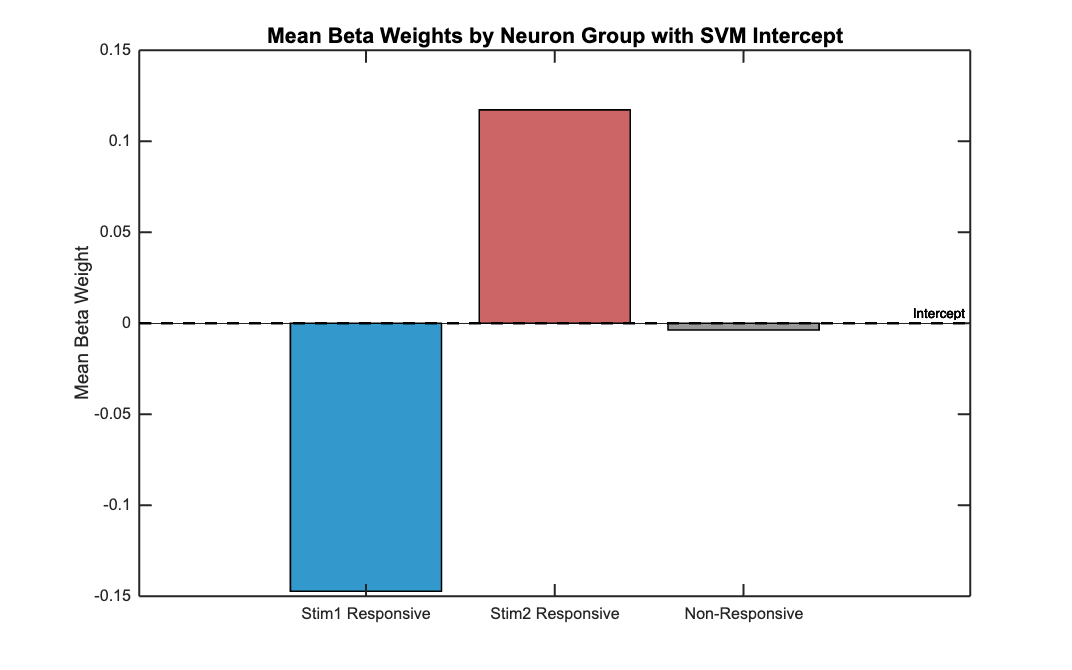



intercept = SVM_out{3}; 
beta_means = [beta_weights_stimulus1, beta_weights_stimulus2, beta_weights_nonresponsive];
group_names = {'Stim1 Responsive', 'Stim2 Responsive', 'Non-Responsive'};

% Plot
figure('Position', [100, 100, 800, 500]);  
bar(beta_means, 'FaceColor', 'flat');     
hold on;

colors = [0.2, 0.6, 0.8; 0.8, 0.4, 0.4; 0.6, 0.6, 0.6];  
for i = 1:length(beta_means)
    bar(i, beta_means(i), 'FaceColor', colors(i, :), 'EdgeColor', 'k', 'LineWidth', 1.2);
end
yline(intercept, '--k', 'LineWidth', 2, 'Label', 'Intercept');

set(gca, 'XTickLabel', group_names, 'FontSize', 12, 'LineWidth', 1.5);
ylabel('Mean Beta Weight', 'FontSize', 14);
title('Mean Beta Weights by Neuron Group with SVM Intercept', 'FontSize', 16);
hold off;